sides = 10;
rComm = 60;
rObs = 30;
agentNum = 10;
partitions = agentNum;
scaleFactor = 1;
maxVelocity = 2;
dt = 1;
distanceTravelled = randi([0,0], agentNum, 1);
energy = randi([1,1], agentNum, 1);
velocityType = "Constant Velocity";
agentPositions = randi(sides*partitions, agentNum, 2);
density = randi([0,10], sides*partitions, sides*partitions);

% density = calcDensity(density,1,sides,partitions);
% density = clusterdata(density, 5);
density = floor(density);

matrix = num2cell(density);
save('density.mat','matrix')

% Initial points assignment
x=0+rand(1,density(1,1))*(1-0);
y=0+rand(1,density(1,1))*(1-0);

for i = 1:sides*partitions
    for j = 1:sides*partitions
        xN = sides*partitions-((i-1)+rand(1,density(i,j))*(i-(i-1)));
        yN = (j-1)+rand(1,density(i,j))*(j-(j-1));
        x = horzcat(x, xN);
        y = horzcat(y, yN);
    end
end

% Bin the data:
pts = linspace(0, sides*partitions, sides*partitions);
N = histcounts2(x(:), y(:), pts, pts);

% Plot data:
scatter(y, x, 1, 'r.');
axis equal;
set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

hold on;

[commCells, adjMatrix] = communication(agentPositions, rComm);
scatter(agentPositions(:,1),agentPositions(:,2),'b*');

agentPoints = assignAgentPoints(agentPositions, commCells, sides*partitions, 1, rObs)

agentPoints = 10×1 cell array
    { 956×2 double}
    {1654×2 double}
    { 498×2 double}
    {1365×2 double}
    { 700×2 double}
    { 492×2 double}
    { 863×2 double}
    {1901×2 double}
    { 648×2 double}
    { 851×2 double}




mass = calcMass(agentPoints,density,partitions)

mass =         4744
        8195
        2564
        7004
        3459
        2510
        4419
        9619
        3249
        4102



centroids = calcCentroids(agentPoints, mass, density, 1, partitions)

centroids =    69.5051   62.3326
   22.0063   39.1359
   92.9216   34.4548
   49.1401   15.9569
   17.6120   91.3073
   93.3092   84.1546
   70.5225   86.9801
   26.8776   75.3675
   84.3161   11.4047
   72.9037   42.0658


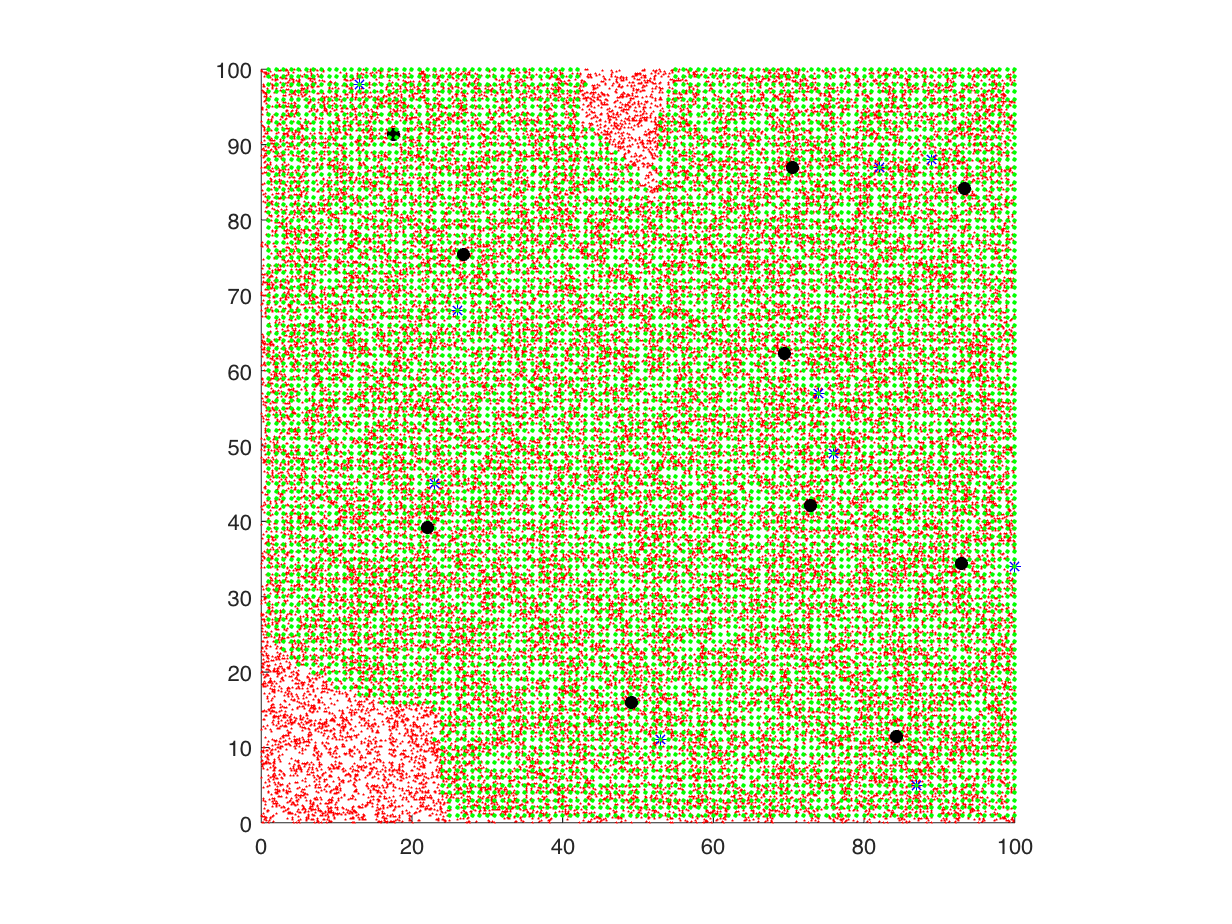



for i = 1:agentNum
    scatter(agentPoints{i}(:,1), agentPoints{i}(:,2), 'g.')
    scatter(centroids(i,1), centroids(i, 2), [], "black", 'filled')
end

hold off;


calcCoverage(agentPoints,1,density,sum(sum(density)))

ans = 0.9475

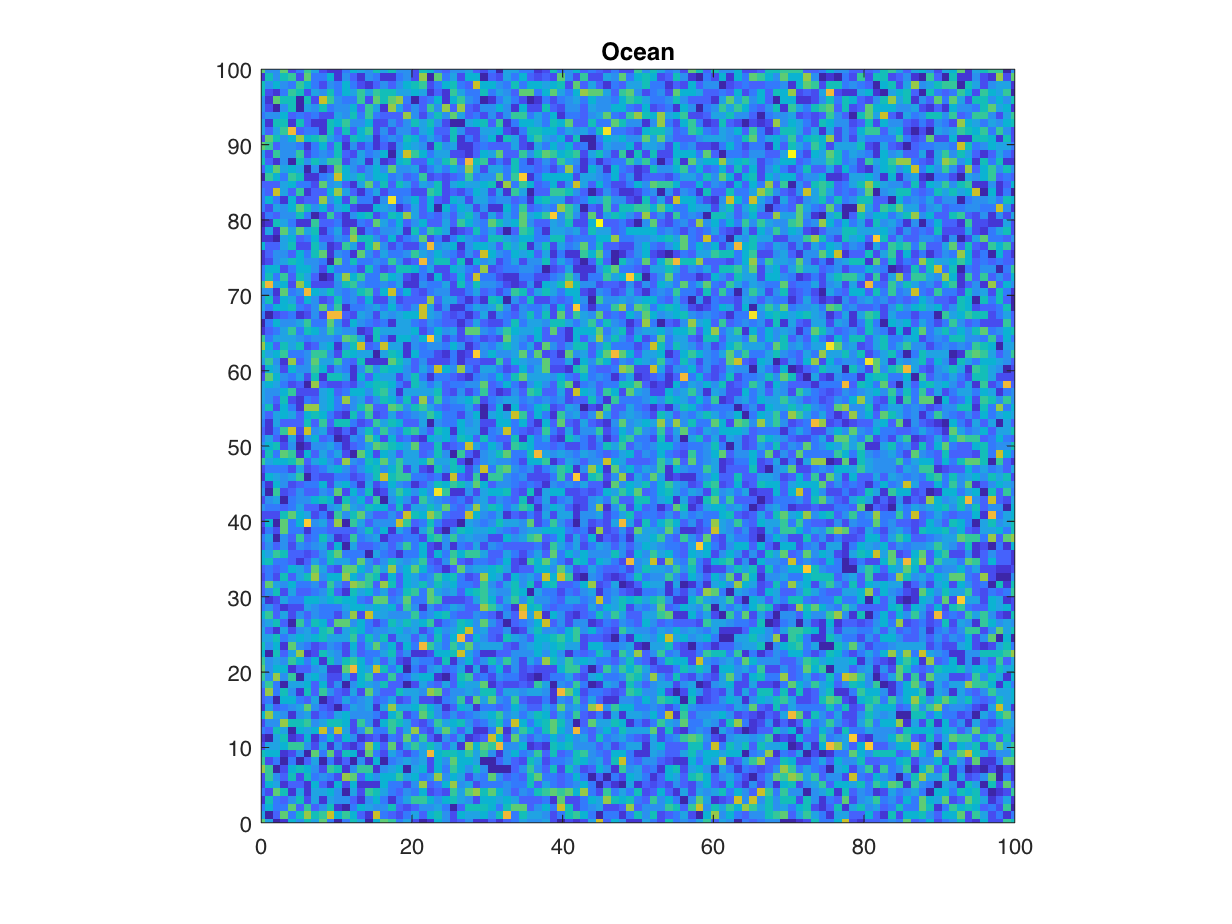


agentPositions; distanceTravelled; energy = moveAgents(agentPositions, ...
    centroids,sides,dt,energy,velocityType,maxVelocity,scaleFactor);



% Plot heatmap:
imagesc(pts, pts, N);
axis equal;
set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]), 'YDir', 'normal');

title('Ocean');